## Numerical Differentiation

In this livescript, you will learn how

- To approximate derivatives using finite differences.

- To determine the error in a finite difference scheme.

To be able to approximate a derivative, we should recall the definition of a derivative 


$$f'(x)=\lim_{\Delta\rightarrow0}{\frac{f(x+\Delta)-f(x)}{\Delta}}$$


What this is saying is the derivative is constructed by looking at what happens when the secant is reduced to a single point.

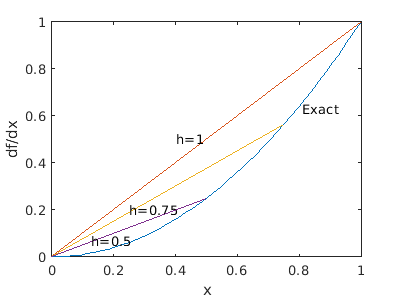

fplot(@(x)x.^2,[0,1])
text(0.81,0.63,sprintf('Exact'))
hold on
plot([0,1],[0,1].^2)
text(0.4,0.5,sprintf('h=1'))
plot([0,0.75],[0,0.75].^2)
text(0.25,0.2,sprintf('h=0.75'))
plot([0,0.5],[0,0.5].^2)
text(0.125,0.07,sprintf('h=0.5'))
xlabel('x')
ylabel('df/dx')
hold off

Therefore, we can approximate the derivative by just supposing that $h$ is very small, giving the *forward difference formula*


$$f'(x)\approx\frac{f(x+\Delta)-f(x)}{\Delta}$$


To formalise this idea, we can use the Taylor series expansion of $f$  


$$f(x)=f(x_{0})+ f'(x_{0})(x-x_{0})+\mathcal{O}(x-x_{0})^{2}$$


Letting $x=x_{0}+\Delta$, we have


$$f(x_{0}+\Delta)=f(x_{0})+ \Delta f'(x_{0})+\mathcal{O}(\Delta^{2})$$


Truncating the series at $\mathcal{O}(\Delta^{2})$ and rearranging for $f'(x_{0})$ gives the *forward difference formula *plus an additional term $\mathcal{O}(\Delta)$, which we call the *truncation error.*

The following piece of code approximates the derivative of $f(x)=x^{2}$ at $x=0.5$.

x = 0.5;
delta = 0.01;

f = @(x) x.^2;

f_dash = (f(x+delta)-f(x))./delta

f_dash = 1.0100

Generalising the code to evaluate the derivative over the interval $[0,2]$, we have

x = linspace(0,2,3);
delta = x(2:end)-x(1:end-1);

f = @(x) x.^2;

f_dash = (f(x(2:end))-f(x(1:end-1)))./delta

f_dash =      1     3


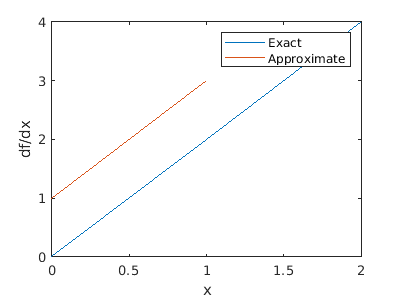


plot(x,2.*x);
hold on
plot(x(1:end-1),f_dash)
legend('Exact','Approximate')
xlabel('x')
ylabel('df/dx')
hold off

(a)        Modify the code to increase the number of points in the interval. See if the numerical derivative converges to the true derivative.

Our derivation of the *forward difference formula* has shown us that the error in the scheme should decrease in the order of $\mathcal{O}(\Delta)
$.

We can look at this by computing the error between the forward difference formula and the exact value of the derivative at $x=1$.

error = zeros(1,10);
f = @(x) x.^2;
x = 1;

for i = 1:10
    delta = 2^-i;
    f_dash = (f(x+delta)-f(x))./delta;
    error(i) = abs(f_dash-2);
end

g = fitlm(log10(2.^-[1:10]),log10(error))

'fitlm' requires Statistics and Machine Learning Toolbox.

plot(g)

However, it is not always obvious how to manipulate these series in order to obtain the finite difference scheme. I find that it's much easier begin with the scheme and substitute in the Taylor series and hope that everything cancels out.

To illustrate this, consider the central difference scheme


$$f_{CD}'(x)=\frac{f(x+\Delta)-f(x-\Delta)}{2\Delta}$$


The Taylor series expansions of $f(x+h)$ and $f(x-h)$ are


$$f(x+\Delta) = f(x)+\Delta f'(x)+\Delta^{2}f''(x)+\mathcal{O}(\Delta^{3})\\
f(x-\Delta) = f(x)-\Delta f'(x)+\Delta^{2}f''(x)+\mathcal{O}(\Delta^{3})$$


Substituting these into the central difference scheme gives


$$f_{CD}'(x)=\frac{[ f(x)+\Delta f'(x)+\Delta^{2}f''(x)+\mathcal{O}(\Delta^{3})]-[ f(x)-\Delta f'(x)+\Delta^{2}f''(x)+\mathcal{O}(\Delta^{3})]}{2\Delta}$$


Upon simplifying this expression, we find 


$$f_{CD}'(x)=\frac{2\Delta f'(x)+\mathcal{O}(\Delta^{3})}{2\Delta}=f'(x)+\mathcal{O}(\Delta^{2})$$


which shows that the truncation error is $\mathcal{O}(\Delta^{2})$.

(b)        Modify the livescript to use the *central difference* and *backward difference* schemes.